%%Try different fitting mothed by fitting to the simulatted polarized gas
%define all the physical constant here:
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
Nsat=330; %PI Camera
warning('off','all');
[ KappaTildeT, PTildeT,TTildeT, Z_vecT ] = IdealFermiEOS( 1,6, 5000 );

First try to Check P/P0 vs Z and kappa/kappa_0 at T/TF=0.1, to show that the EoS program works well with no noise data.

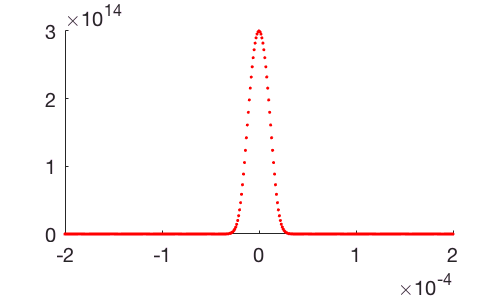

load('polarized_simulated_T0_1_noise_hires.mat');
h=figure('position',[1,1,250,150]);
scatter(y_vec,n_simulated,'r.')

% scatter(y_vec,PTilde)
Z=y_vec;

n=n_simulated(Z>=0);
PTilde=PTilde(Z>=0);
KappaTilde=KappaTilde(Z>=0);
Z=Z(Z>=0);
V=0.5*mli*omega^2*Z.^2;

[Vsort,B]=sort(V);
nsort=n(B);
Zsort=Z(B);
PTildesort=PTilde(B);
KappaTildesort=KappaTilde(B);
[~,~,Pt]=GetPvsV(nsort,Vsort);
Kt=GetKappavsVPoly(nsort,Vsort,20,8);


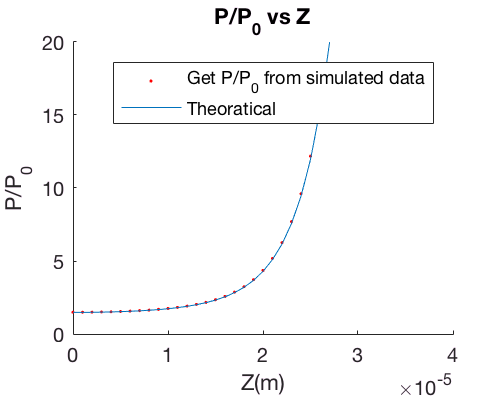

%Plot the image for last section
figure1 = figure('Name','Figure','position',[1,1,250,200]);
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot1=plot(Zsort,Pt,'r.');
plot2=plot(Zsort,PTildesort);
set(plot1,'DisplayName','Get P/P_0 from simulated data','Marker','.',...
    'LineStyle','none',...
    'Color',[1 0 0]);
set(plot2,'DisplayName','Theoratical');
ylim([0,20]);xlim([0,0.4e-4])
xlabel('Z(m)');ylabel('P/P_0');
legend(axes1,'show');
hold(axes1,'off')
title('P/P_0 vs Z');

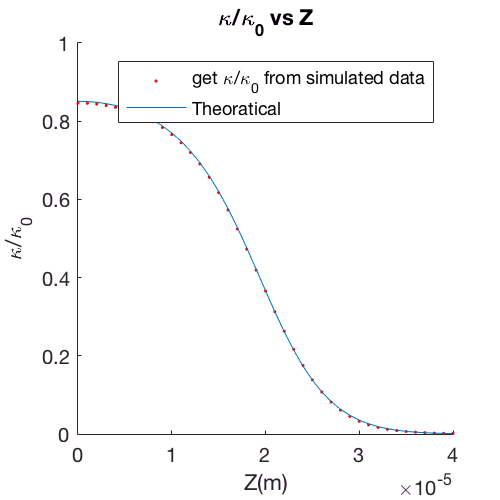


figure2=figure('Name','Figure','position',[1,1,250,250]);
axes2=axes('Parent',figure2);
hold(axes2,'on');
plot1=plot(Zsort,Kt,'r.');
plot2=plot(Zsort,KappaTildesort);
set(plot1,'DisplayName','get \kappa/\kappa_0 from simulated data');
set(plot2,'DisplayName','Theoratical');
ylim([0,1]);xlim([0,0.4e-4]);
legend(axes2,'show');
hold(axes2,'off');
xlabel('Z(m)');ylabel('\kappa/\kappa_0');
title('\kappa/\kappa_0 vs Z');

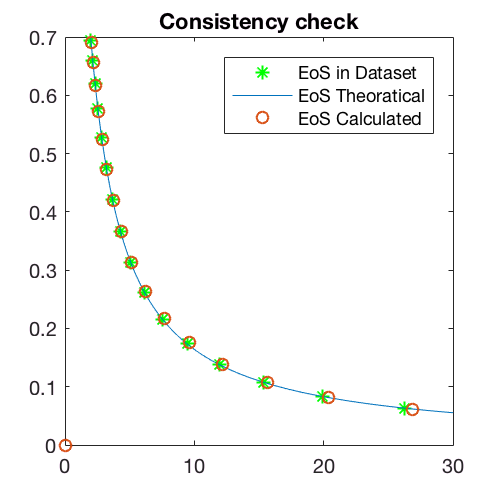

h3=figure('position',[1,1,250,250]);
p1=plot(PTildesort,KappaTildesort,'g*');
hold on
xlim([0,30]);ylim([0,0.7])
p2=plot(PTildeT,KappaTildeT);
p3=scatter(Pt,Kt);
set(p1,'DisplayName','EoS in Dataset');
set(p2,'DisplayName','EoS Theoratical');
set(p3,'DisplayName','EoS Calculated');
legend('show');
title('Consistency check');
hold off

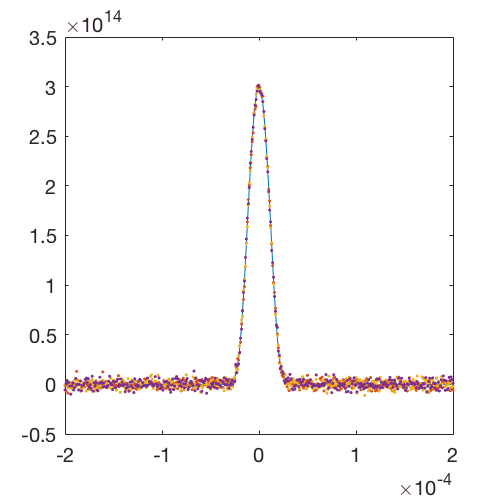

%% Now Try to play around with the noisy data
%Randomly pick 3 data sets and show the EoS
load('polarized_simulated_T0_1_noise_hires.mat');

n_noise1=n_simulated_noise_list{1};
n_noise2=n_simulated_noise_list{10};
n_noise3=n_simulated_noise_list{20};

noiseplot=figure('position',[1,1,250,250]);
plot(y_vec,n_simulated);
hold on
scatter(y_vec,n_noise1,'.');
scatter(y_vec,n_noise2,'.');
scatter(y_vec,n_noise3,'.');
hold off

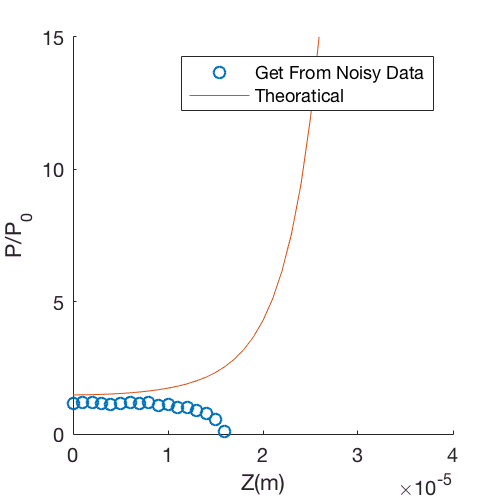


Z=y_vec;
V=0.5*mli*omega^2*Z.^2;
V=V(Z>=0);
PTildeSide=PTilde(Z>=0);
KappaTildeSide=KappaTilde(Z>=0);
n_noise1=n_noise1(Z>=0);
n_noise2=n_noise2(Z>=0);
n_noise3=n_noise3(Z>=0);
Z=Z(Z>=0);
[Vsort,B]=sort(V);
n_noise1_sort=n_noise1(B);
n_noise2_sort=n_noise2(B);
n_noise3_sort=n_noise3(B);
Zsort=Z(B);
PTildesort=PTildeSide(B);
KappaTildesort=KappaTildesort(B);
[~,~,Pt1]=GetPvsV(n_noise1_sort,Vsort);

p1=scatter(Zsort,Pt1);
hold on
p2=plot(Zsort,PTildesort);
ylim([0,15]);xlim([0,0.4e-4])
ylabel('P/P_0');xlabel('Z(m)');
set(p1,'displayname','Get From Noisy Data');
set(p2,'displayname','Theoratical');
legend('show');
hold off

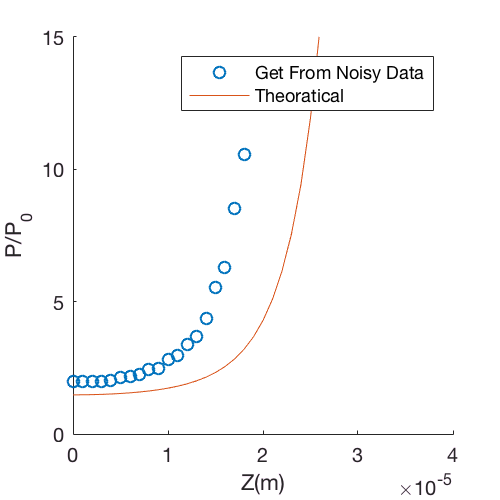


[~,~,Pt2]=GetPvsV(n_noise2_sort,Vsort);

p1=scatter(Zsort,Pt2);
hold on
p2=plot(Zsort,PTildesort);
ylim([0,15]);xlim([0,0.4e-4])
ylabel('P/P_0');xlabel('Z(m)');
set(p1,'displayname','Get From Noisy Data');
set(p2,'displayname','Theoratical');
legend('show');
hold off

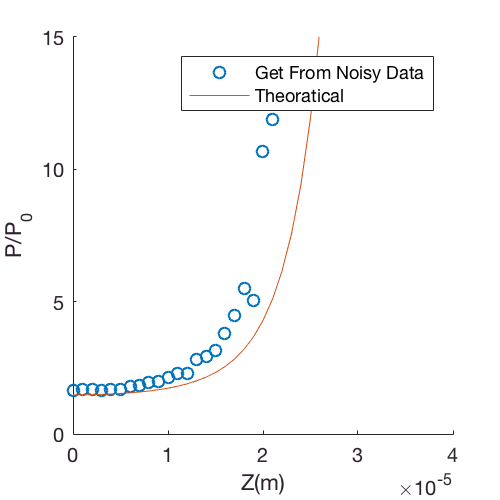


[~,~,Pt3]=GetPvsV(n_noise3_sort,Vsort);

p1=scatter(Zsort,Pt3);
hold on
p2=plot(Zsort,PTildesort);
ylim([0,15]);xlim([0,0.4e-4])
ylabel('P/P_0');xlabel('Z(m)');
set(p1,'displayname','Get From Noisy Data');
set(p2,'displayname','Theoratical');
legend('show');
hold off

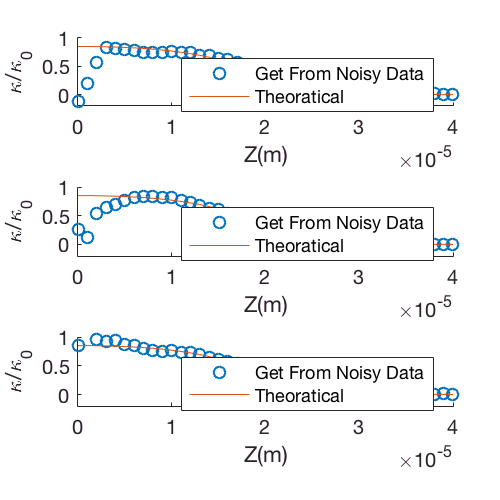

Kt1=GetKappavsVPoly(n_noise1_sort,Vsort,10,4);
subplot(3,1,1);
p1=scatter(Zsort,Kt1);
hold on
p2=plot(Zsort,KappaTildesort);
ylim([-0.2,1]);xlim([0,0.4e-4])
ylabel('\kappa/\kappa_0');xlabel('Z(m)');
set(p1,'displayname','Get From Noisy Data');
set(p2,'displayname','Theoratical');
legend('show');
hold off

Kt2=GetKappavsVPoly(n_noise2_sort,Vsort,10,4);
subplot(3,1,2);
p1=scatter(Zsort,Kt2);
hold on
p2=plot(Zsort,KappaTildesort);
ylim([-0.2,1]);xlim([0,0.4e-4])
ylabel('\kappa/\kappa_0');xlabel('Z(m)');
set(p1,'displayname','Get From Noisy Data');
set(p2,'displayname','Theoratical');
legend('show');
hold off

Kt3=GetKappavsVPoly(n_noise3_sort,Vsort,10,4);
subplot(3,1,3);
p1=scatter(Zsort,Kt3);
hold on
p2=plot(Zsort,KappaTildesort);
ylim([-0.2,1]);xlim([0,0.4e-4])
ylabel('\kappa/\kappa_0');xlabel('Z(m)');
set(p1,'displayname','Get From Noisy Data');
set(p2,'displayname','Theoratical');
legend('show');
hold off

Tried the simpson integration, the outcome is similar compared to trapz

% n_noise2_sort=n_noise2(Zsort<.4e-4);
% Vsort=Vsort(Zsort<.4e-4);
% PTildesort=PTildesort(Zsort<.4e-4);
% Zsort=Zsort(Zsort<.4e-4);
% 
% [~,~,Pt2Simps]=GetPvsV(n_noise2_sort,Vsort);
% p1=scatter(Zsort,Pt2Simps);
% hold on
% p2=plot(Zsort,PTildesort);
% ylim([0,15]);xlim([0,0.3e-4])
% ylabel('P/P_0');xlabel('Z(m)');
% set(p1,'displayname','Get From Noisy Data');
% set(p2,'displayname','Theoratical');
% legend('show');
% title('With Simpson Integration')
% hold off

Try changing the cutoff for the integration, see what will hapen

load('polarized_simulated_T0_1_noise_hires.mat');
n=n_simulated_noise_list{1};
Z=y_vec;
Ptf=TFfit(n,Z,2.5e-5);
Ztf=abs(Ptf(3));
Cutoff=1:0.5:8;
Cutoff=[Cutoff,inf];
N=length(Cutoff)

N = 16

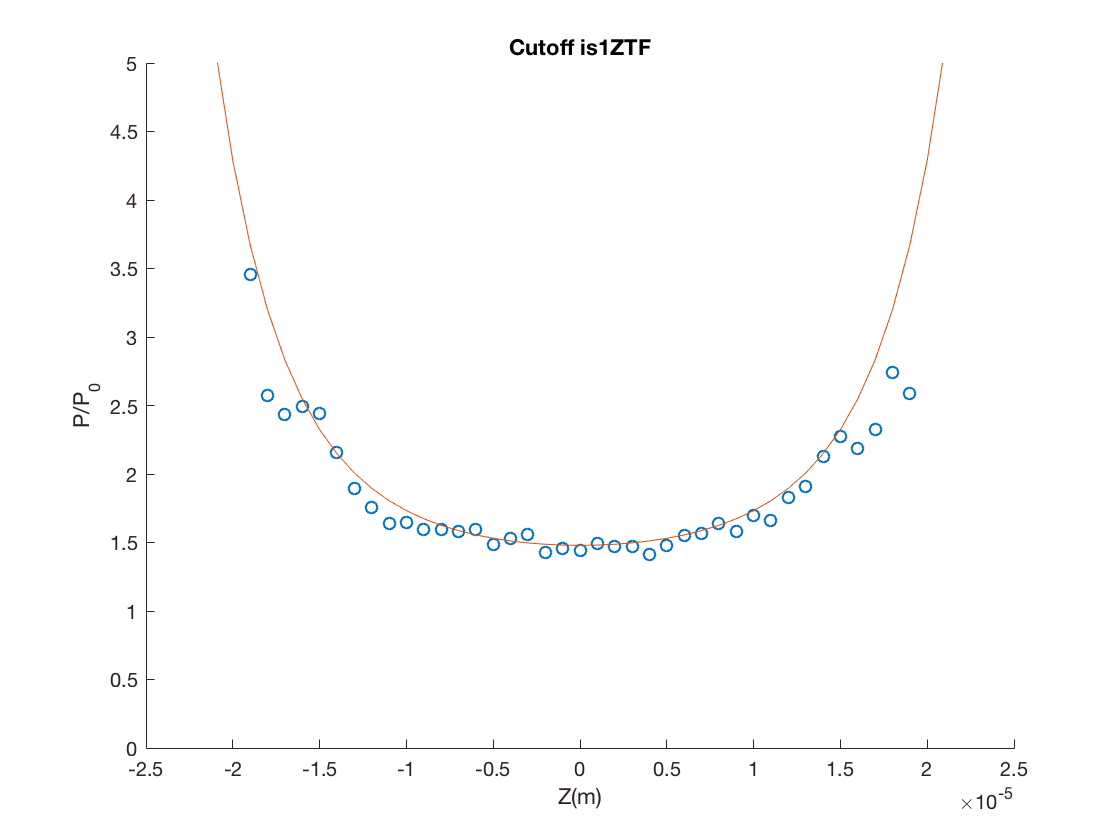

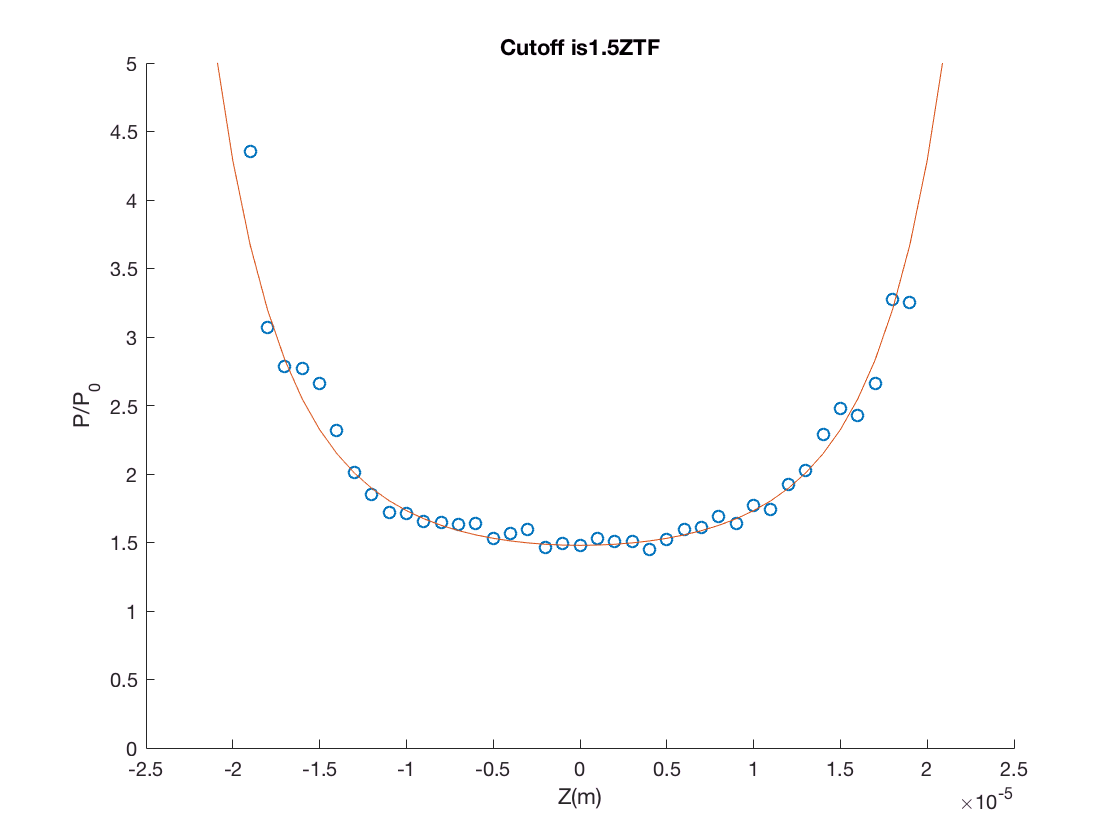

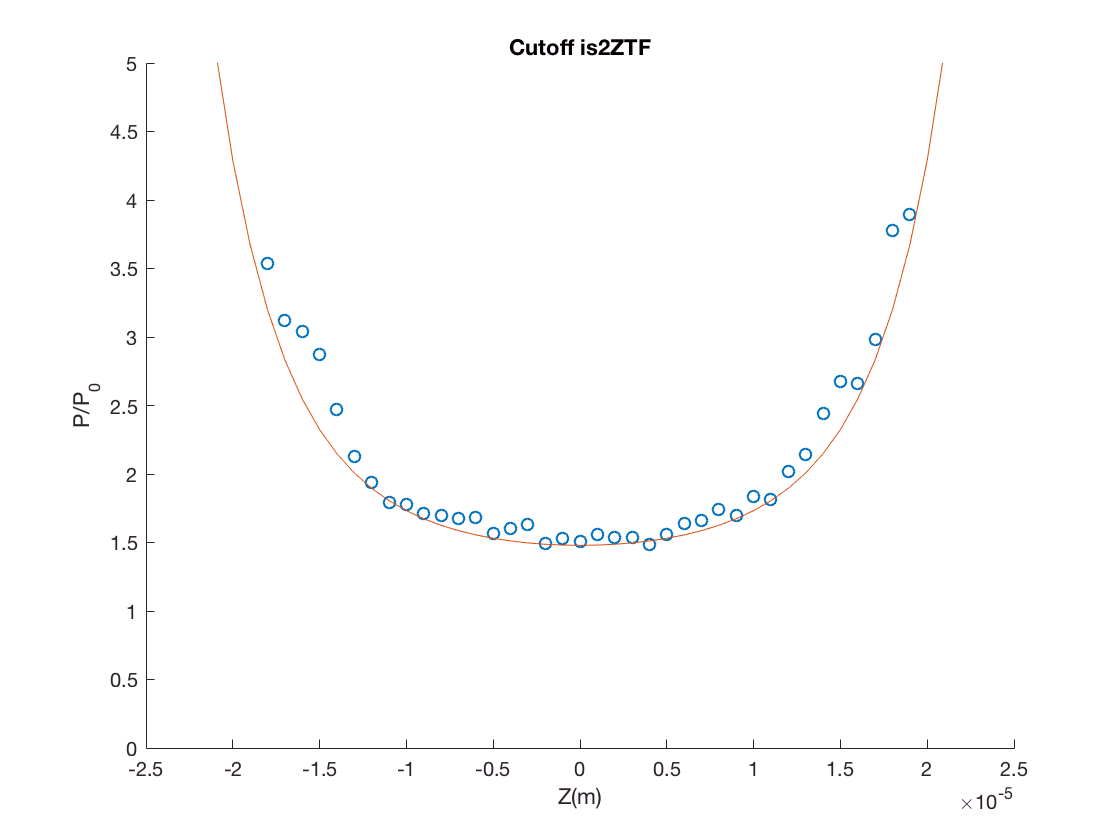

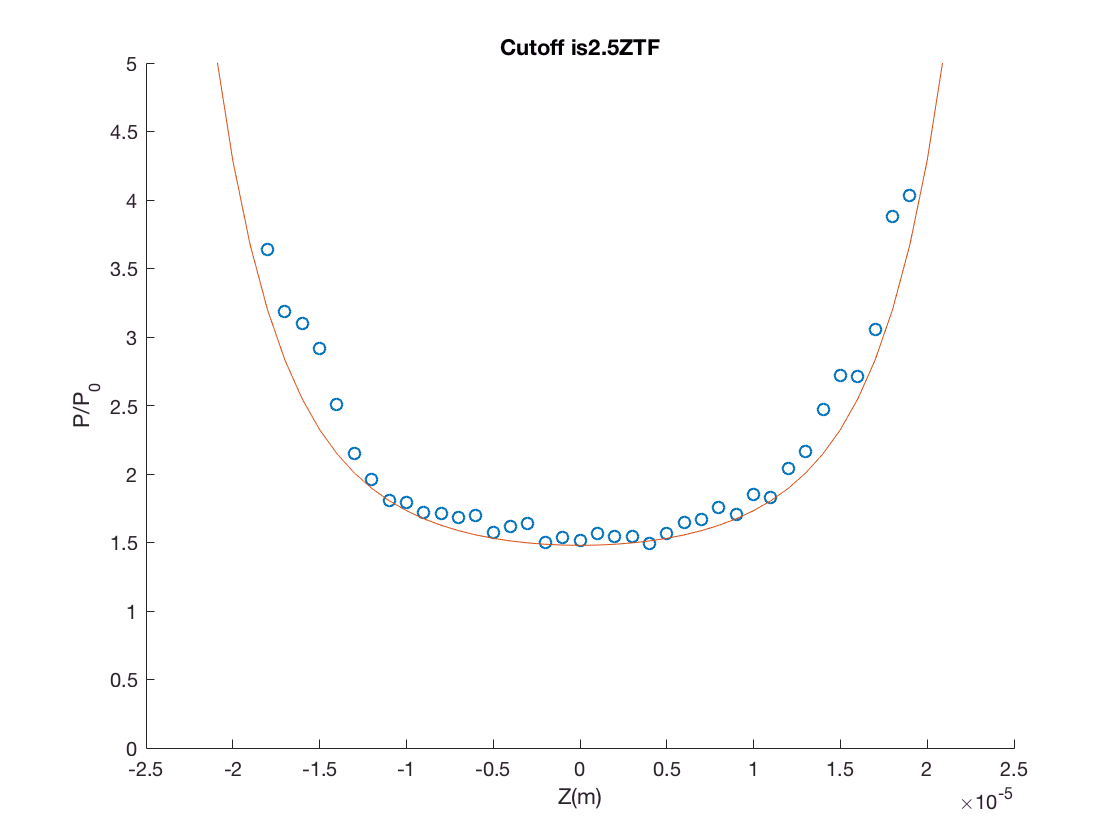

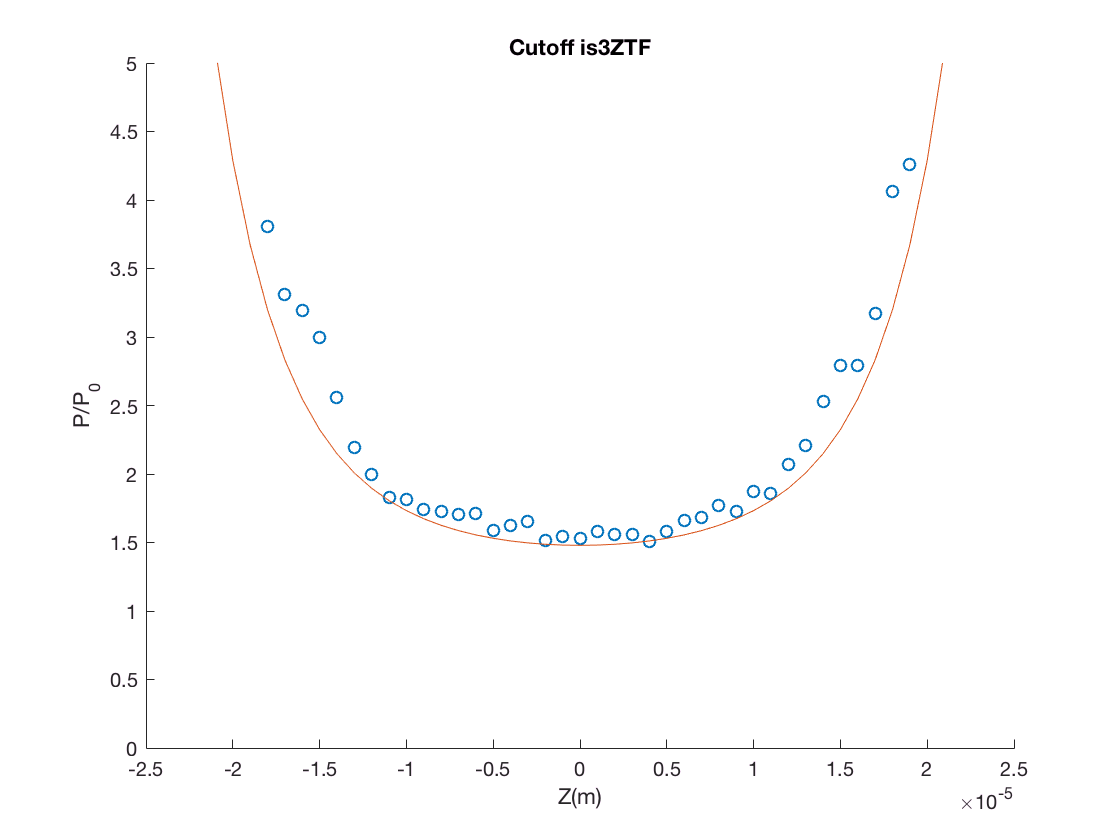

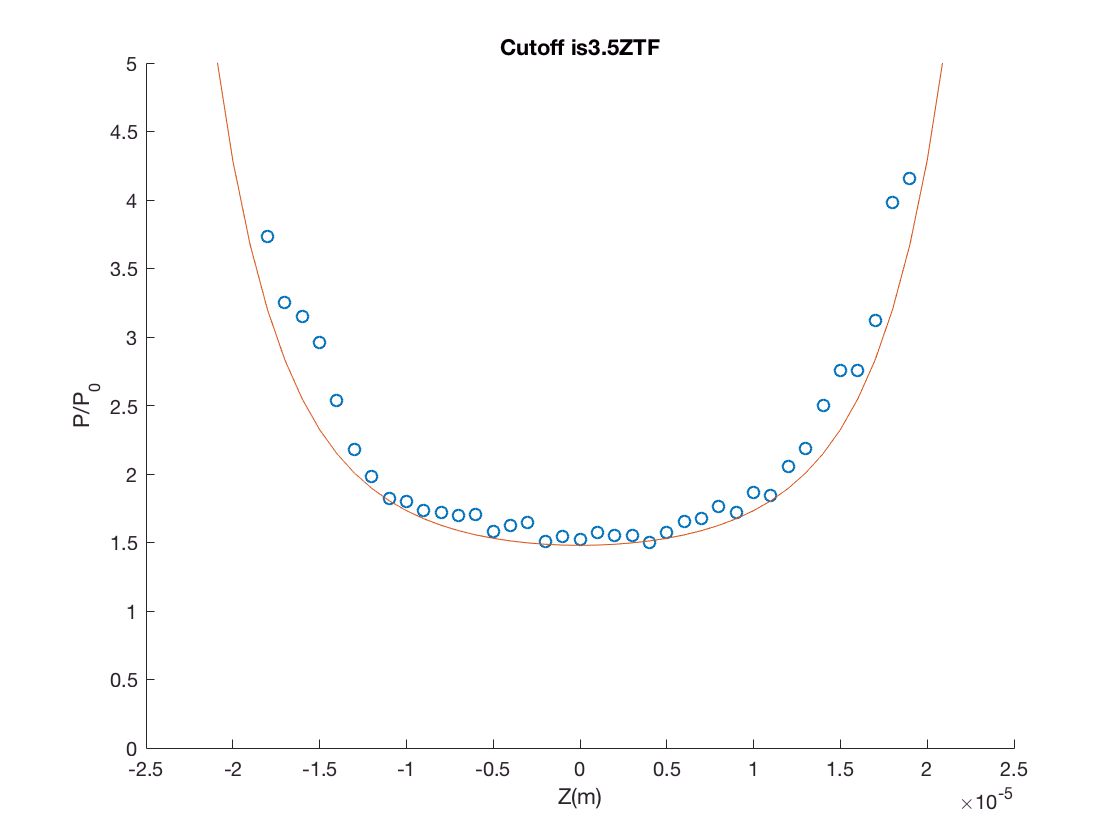

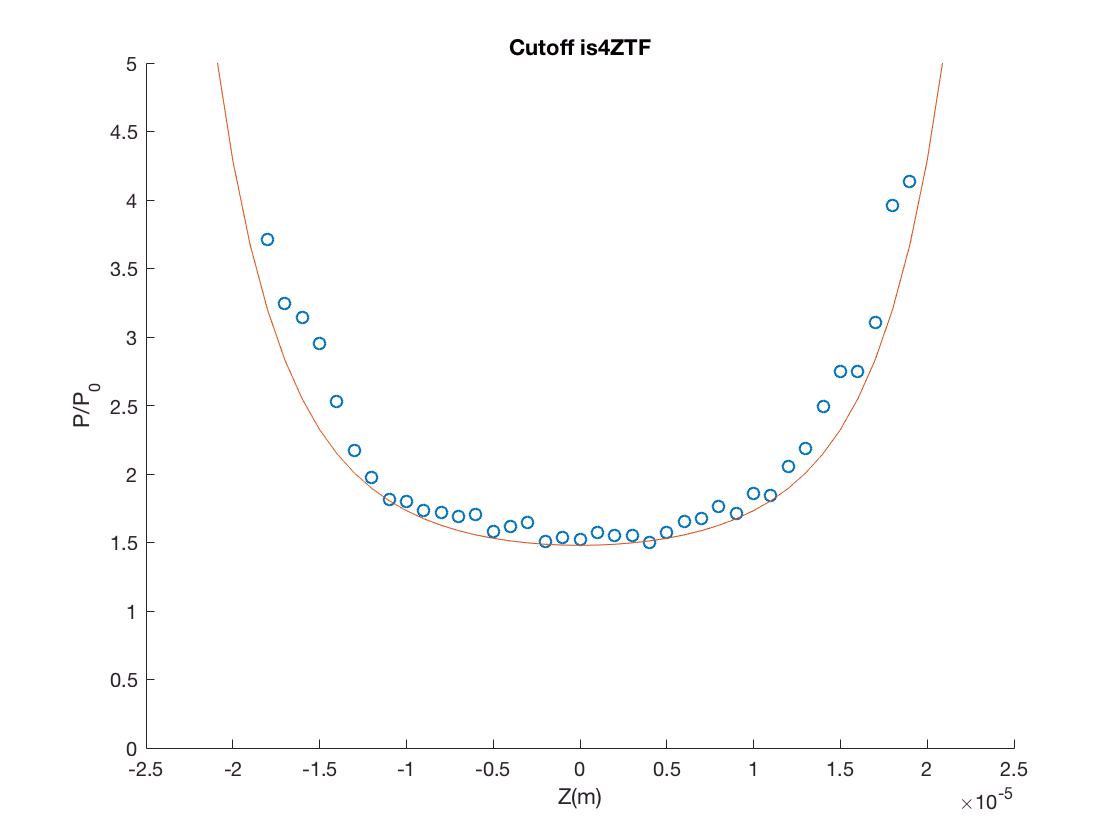

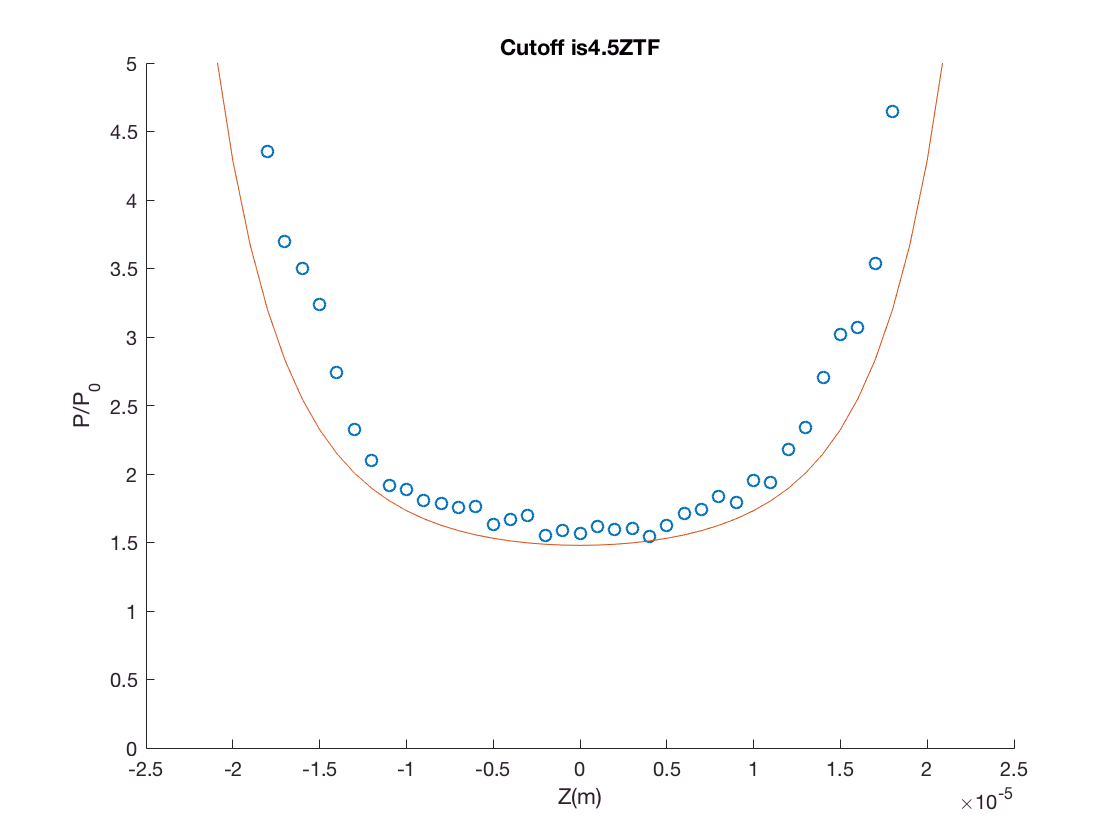

Pt=cell(N,1);
Ptsel=Pt;
Error=0*Cutoff;
kmin=0.05;
kmax=0.8;
for i=1:N
    CutoffZ=Cutoff(i)*Ztf;
    PTilde_cutoff=PTilde(abs(Z)<CutoffZ);
%     KTilde_cutoff=PTilde(Z<CutoffZ);
    n_cutoff=n(abs(Z)<CutoffZ);
    Z_cutoff=Z(abs(Z)<CutoffZ);
    V_cutoff=0.5*mli*omega^2*Z_cutoff.^2;
    [Vsort,B]=sort(V_cutoff);
    nsort=n_cutoff(B);
    Zsort=Z_cutoff(B);
    PTilde_sort=PTilde_cutoff(B);
    
    [~,~,Pt{i}]=GetPvsV(nsort,Vsort);
    Zmax=Ztf*kmax;
    Zmin=Ztf*kmin;
    %delete the guys on wings
    Pt_temp=Pt{i};
    Ptsel{i}=Pt_temp(abs(Zsort)<Zmax);
    PTilde_sel=PTilde_sort(abs(Zsort)<Zmax);
    Zsel=Zsort(abs(Zsort)<Zmax);
    Error(i)=sum((Ptsel{i}-PTilde_sel).^2);
    h=figure;
    scatter(Zsel,Ptsel{i});
    hold on
    plot(Z,PTilde);
    xlabel('Z(m)');ylabel('P/P_0');
    xlim([-2.5e-5,2.5e-5]);ylim([0,5])
    title(['Cutoff is',num2str(Cutoff(i)),'ZTF'])
    hold off
end

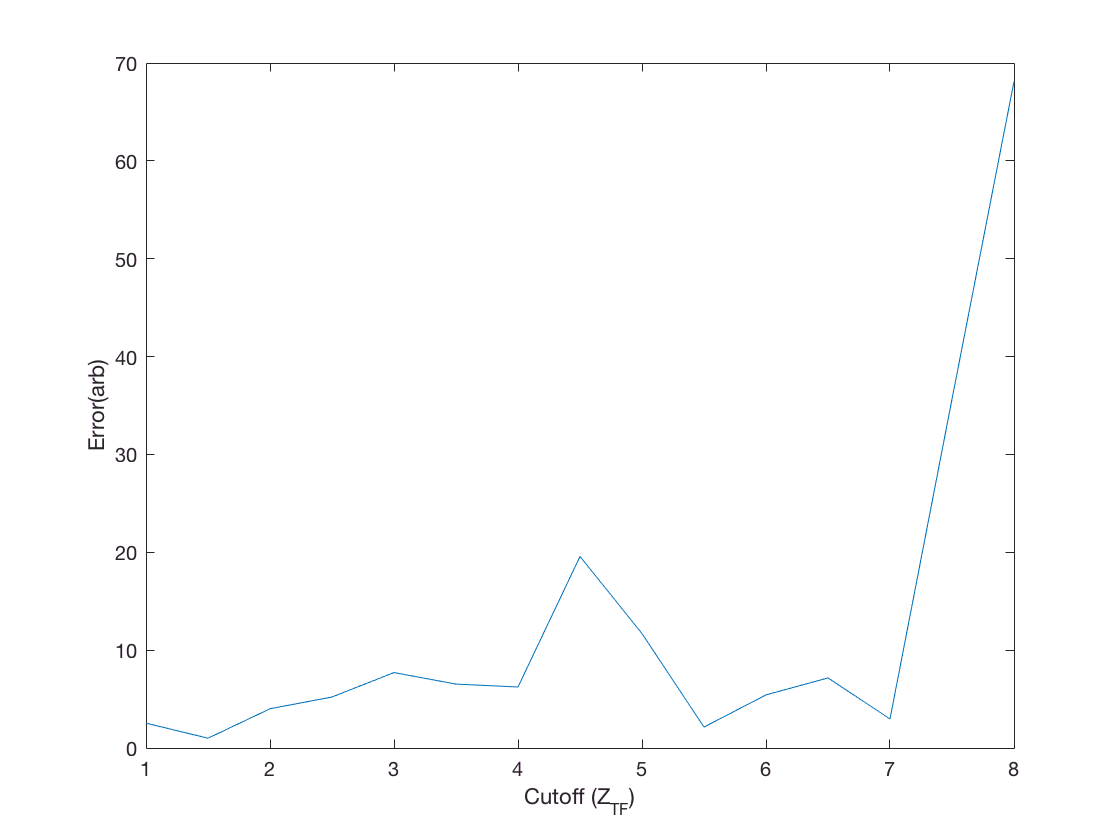

plot(Cutoff,Error);
xlabel('Cutoff (Z_{TF})'); ylabel('Error(arb)');

% N=length(n_simulated_noise_list);
% Ptlist=[];
% Ktlist=[];
% Zlist=[];
% for i=1:N
%     Z=y_vec';
%     n=n_simulated_noise_list{i}';
%     n=n(Z>=0);
%     Z=Z(Z>=0);
%     V=0.5*mli*omega^2*Z.^2;
%     [Vsort,B]=sort(V);
%     nsort=n(B);
%     Zsort=Z(B);
%     
%     [~,~,Pt]=GetPvsV(nsort,Vsort);
%     Kt=GetKappavsV(nsort,Vsort);
%     
%     Pt(Z>3.5e-5)=[];Kt(Z>3.5e-5)=[];
%     Pt(Z<.35e-5)=[];Kt(Z<.35e-5)=[];
%     Ptlist=[Ptlist;Pt];Ktlist=[Ktlist;Kt];
% end
% 

% PtBinMin=0;
% PtBinMax=30;
% dPt=0.2;
% Ptbin=PtBinMin:dPt:PtBinMax;
% Nbin=size(Ptbin,2);
% M=length(Ktlist);
% KtBinList=cell(1,Nbin);
% KtMean=zeros(1,Nbin);
% KtStd=zeros(1,Nbin);
% for i=1:Nbin
%     KtBinList{i}=[];
% end
% 
% for i=1:M
%     K=round((Ptlist(i)-PtBinMin)/dPt+1);
%     if K<=Nbin && K>=1
%         temp=KtBinList{K};
%         KtBinList{K}=[temp,Ktlist(i)];
%     end
% end
% 
% for i=1:Nbin
%     KtMean(i)=mean(KtBinList{i});
%     KtStd(i)=std(KtBinList{i});
% end

% figure
% errorbar(Ptbin,KtMean,KtStd);
% hold on
% plot(PTildeT,KappaTildeT)
% hold off
% xlim([0,30]);ylim([0,1]);

Get the EoS for the simulated data from deferent center T/TF

load('MultipleTSimulated_noise');
N=length(n_simulated_noise_list_multiT);
Ptlist=[];
Ktlist=[];
for i=1:N
    [~,~,~,~,~,Ptsel,Ktsel] = ...
    GenerateEoS( n_simulated_noise_list_multiT{i},y_vec, mli,omega,2,0.2,0.8,20,4);
    Ptlist=[Ptlist,Ptsel];
    Ktlist=[Ktlist,Ktsel];
end


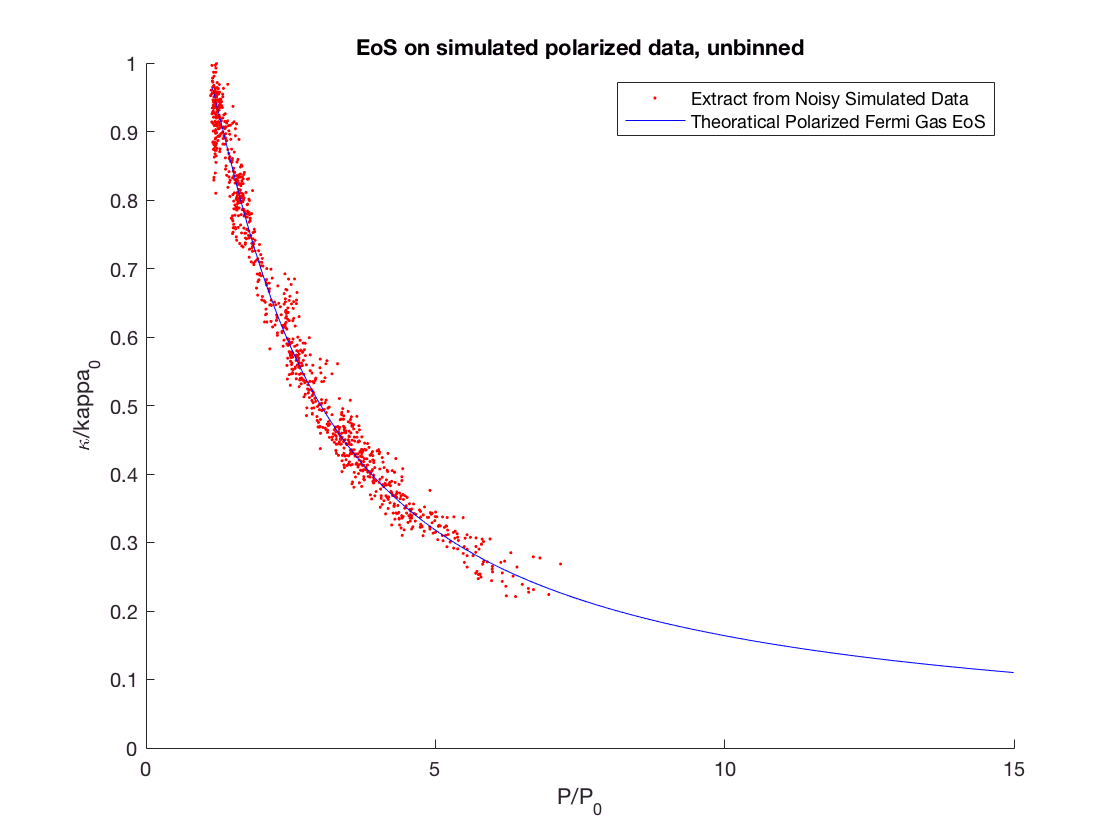

%plot the unbinned data
p1=scatter(Ptlist,Ktlist,'r.');
hold on
p2=plot(PTildeT,KappaTildeT,'b');
hold off
xlim([0,15]);ylim([0,1]);
xlabel('P/P_0');ylabel('\kappa/kappa_0');
set(p1,'DisplayName','Extract from Noisy Simulated Data');
set(p2,'DisplayName','Theoratical Polarized Fermi Gas EoS');
title('EoS on simulated polarized data, unbinned');
legend('show');

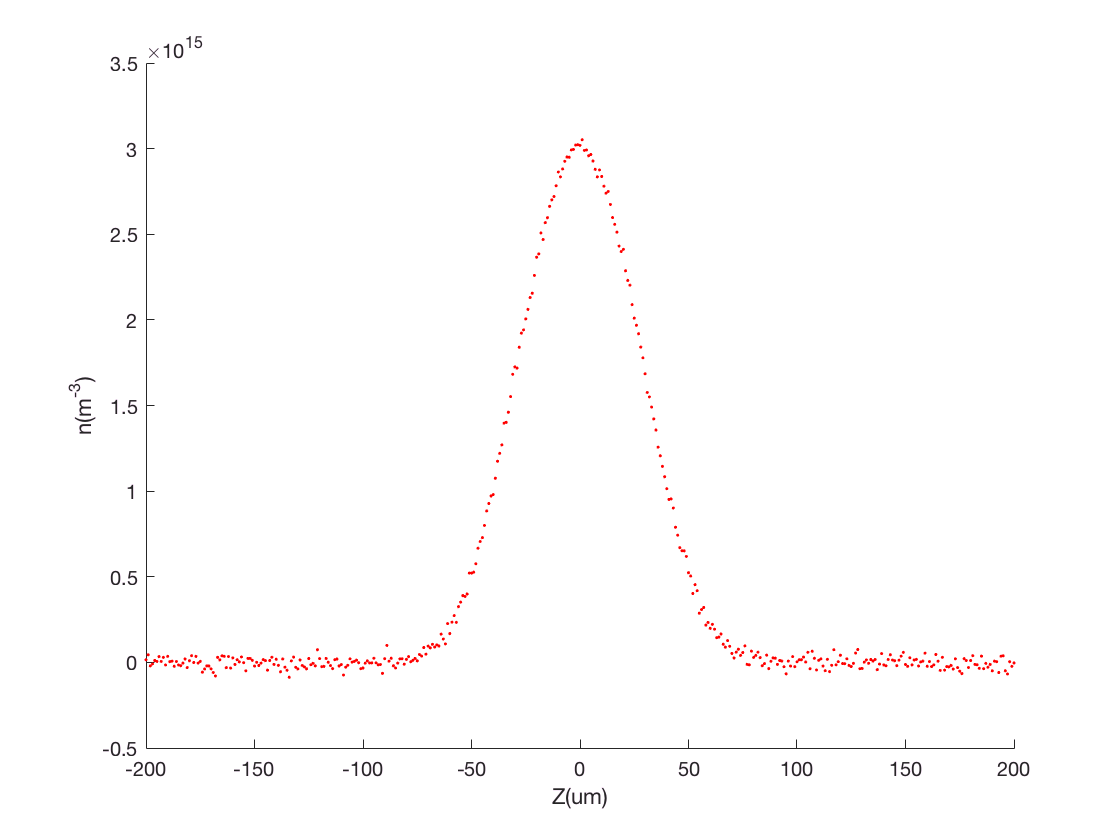

%plot the original Z vs n profile
scatter(y_vec/1e-6,n_simulated_noise_list_multiT{8},'r.')
xlabel('Z(um)');ylabel('n(m^{-3})')

Bin the data

Ktlist(Ptlist<0.95)=[];
Ptlist(Ptlist<0.95)=[]

Ptlist =     3.5408    3.4135    3.4213    3.4495    3.4355    3.5487    3.5380    3.3803    3.6794    3.5695    3.6492    3.6462    3.6544    3.6494    3.5590    3.5923    3.7259    3.5695    3.6877    3.9709    3.6735    3.7954    3.8007    3.7437    3.9203    3.8726    3.9368    3.8710    4.0189    4.0356    4.0820    4.3165    4.2546    4.2945    4.1930    4.3048    4.2331    4.3822    4.3927    4.4076    4.3743    4.8641    4.4076    4.5914    4.8085    4.9610    4.7884    4.4280    5.1580    4.7396



PtBinMin=0;
PtBinMax=6;
dPt=0.1;
Ptbin=PtBinMin:dPt:PtBinMax;
Nbin=size(Ptbin,2);
M=length(Ktlist);
KtBinList=cell(1,Nbin);
KtMean=zeros(1,Nbin);
KtStd=zeros(1,Nbin);
for i=1:Nbin
    KtBinList{i}=[];
end

for i=1:M
    K=round((Ptlist(i)-PtBinMin)/dPt+1);
    if K<=Nbin && K>=1
        temp=KtBinList{K};
        KtBinList{K}=[temp,Ktlist(i)];
    end
end

for i=1:Nbin
    KtMean(i)=mean(KtBinList{i});
    KtStd(i)=std(KtBinList{i});
end

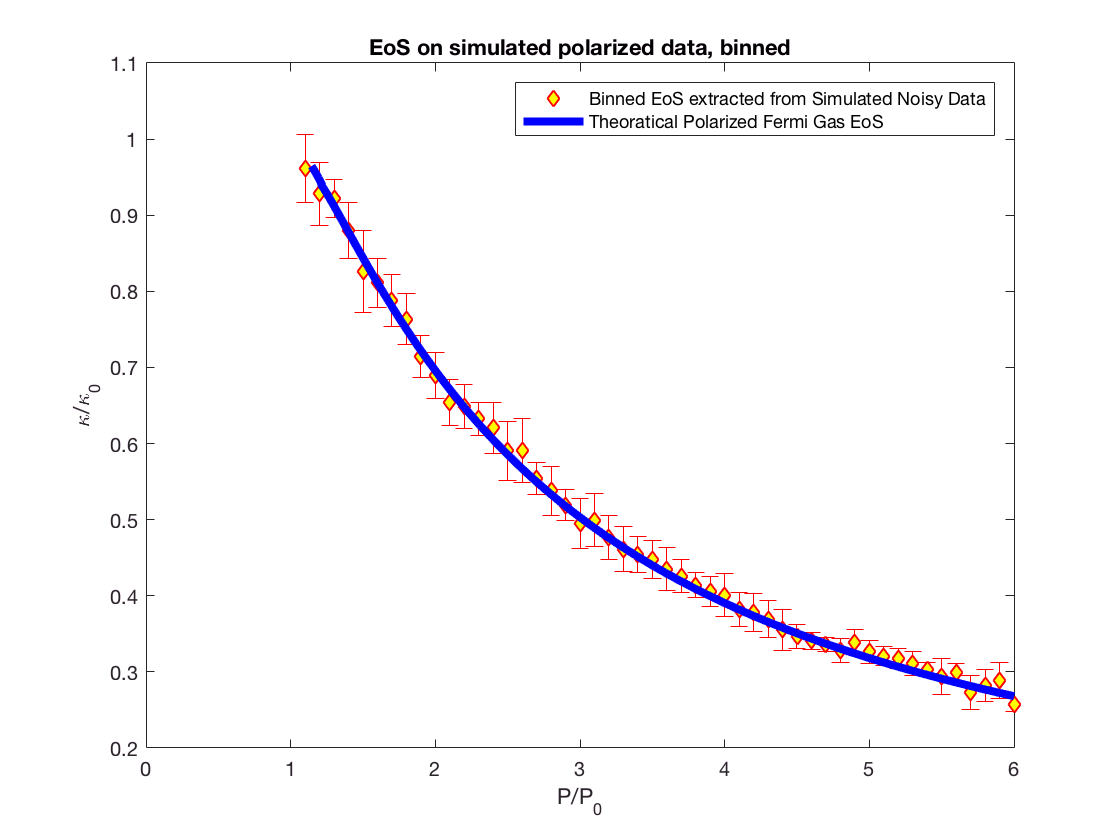

%plot the binned data
p1=errorbar(Ptbin,KtMean,KtStd,'LineStyle','none','Color',[1,0,0]);
set(p1,'MarkerFaceColor',[1 1 0],'Marker','diamond');
set(p1,'DisplayName','Binned EoS extracted from Simulated Noisy Data');
hold on
p2=plot(PTildeT,KappaTildeT,'b' ,'LineWidth',4);
set(p2,'DisplayName','Theoratical Polarized Fermi Gas EoS');
legend('show');
xlabel('P/P_0');ylabel('\kappa/\kappa_0');
xlim([0,6]);
title('EoS on simulated polarized data, binned');
hold off

Get the T/T_F from the EoS

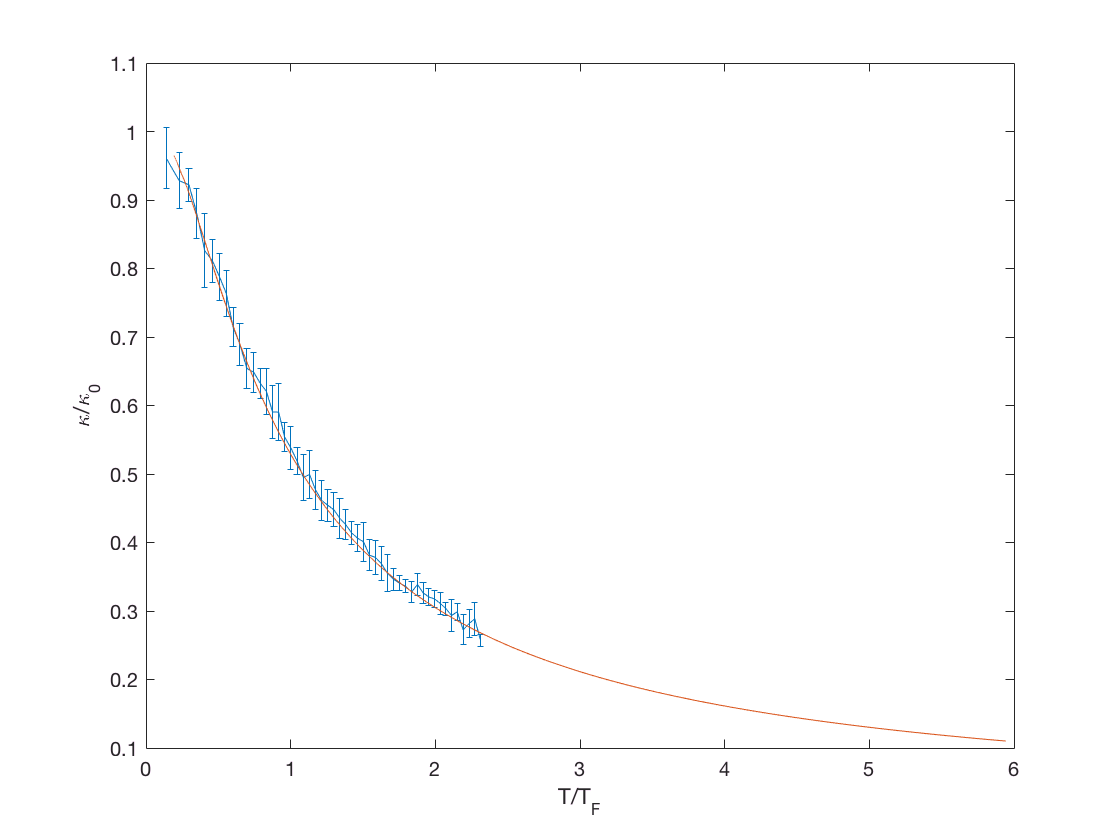

Ptbin(isnan(KtMean))=[];
KtStd(isnan(KtMean))=[];
KtMean(isnan(KtMean))=[];

addpath('../Library')
Ptend=Ptbin(end);
Ttend=interp1(PTildeT,TTildeT,Ptend);
Tt=GetTTilde(Ptbin,KtMean,Ttend);
errorbar(Tt,KtMean,KtStd);
hold on
plot(TTildeT,KappaTildeT);
hold off
xlabel('T/T_F');ylabel('\kappa/\kappa_0');

Doesn't looks so good at low temperature regime

Try P/P_0 vs T/T_F

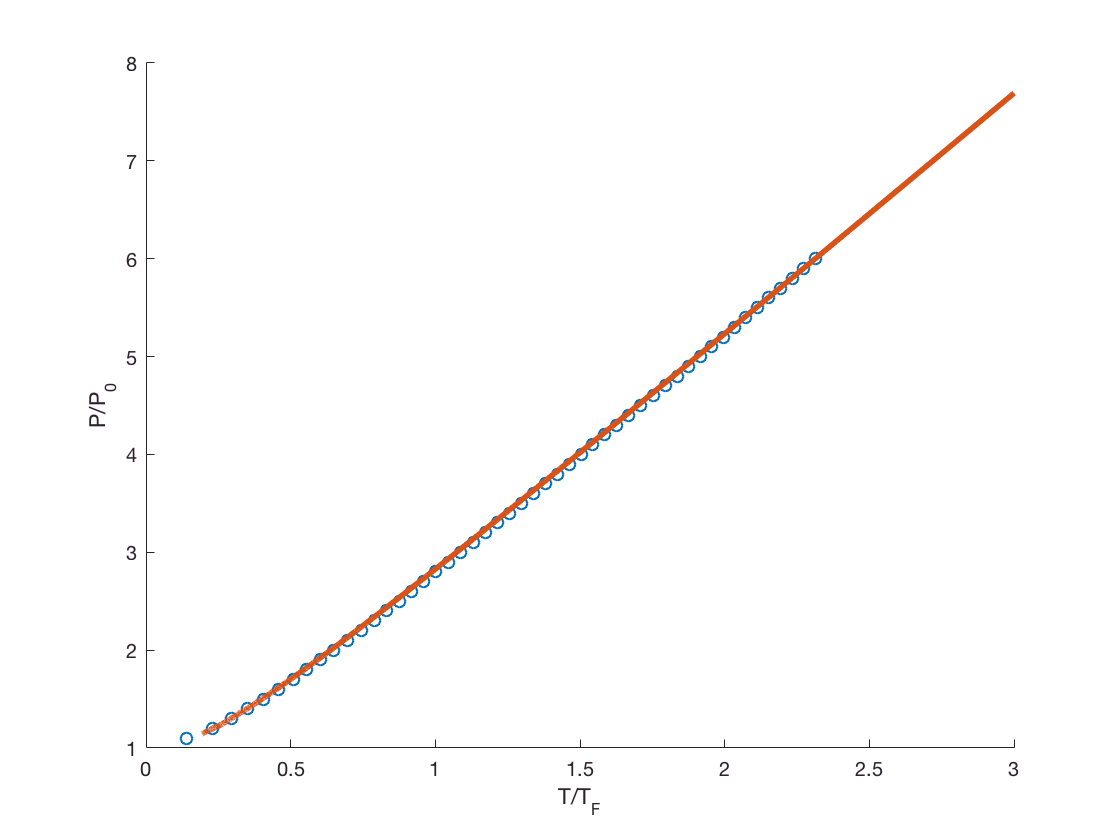

scatter(Tt,Ptbin)
hold on
plot(TTildeT,PTildeT,'linewidth',3);
hold off
xlabel('T/T_F');
ylabel('P/P_0');
xlim([0,3])

Get Cv vs T/TF   

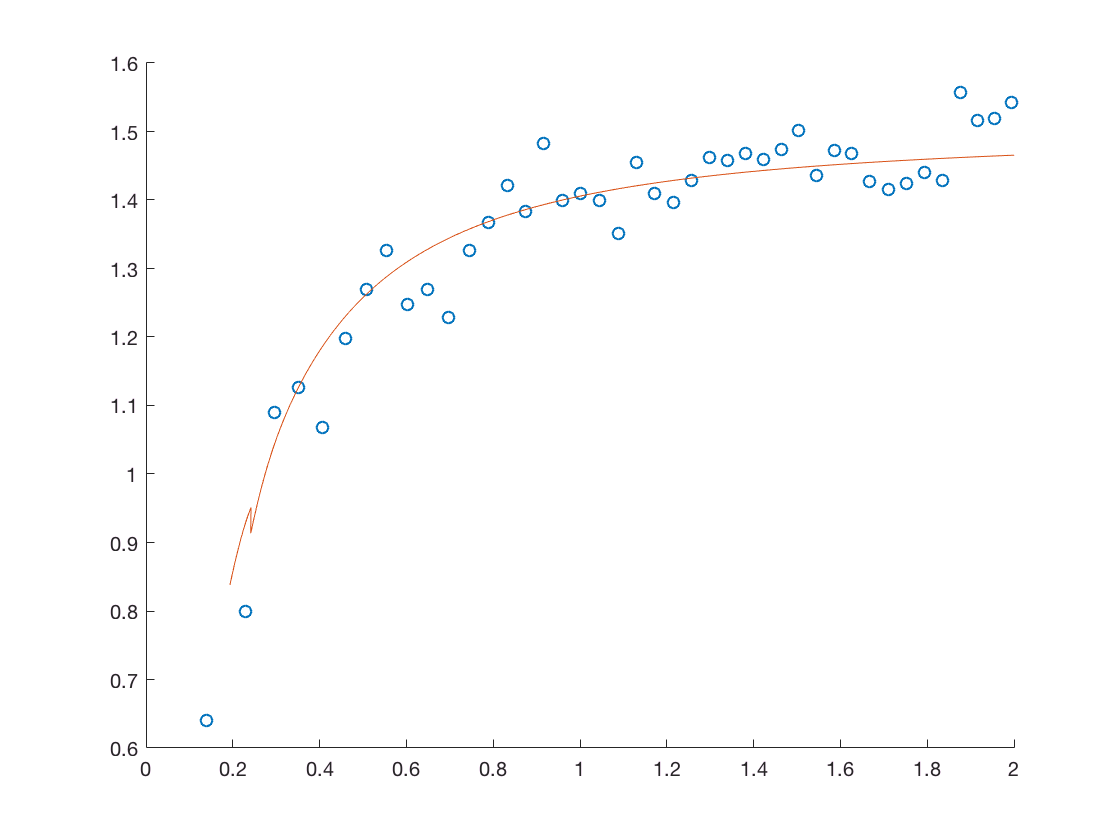

CvTilde_Sim = GetCvTilde( Ptbin,KtMean,Tt);
CvTildeT=GetCvTilde( PTildeT,KappaTildeT,TTildeT );
scatter(Tt,CvTilde_Sim);
hold on
plot(TTildeT,CvTildeT);
hold off
xlim([0,2])

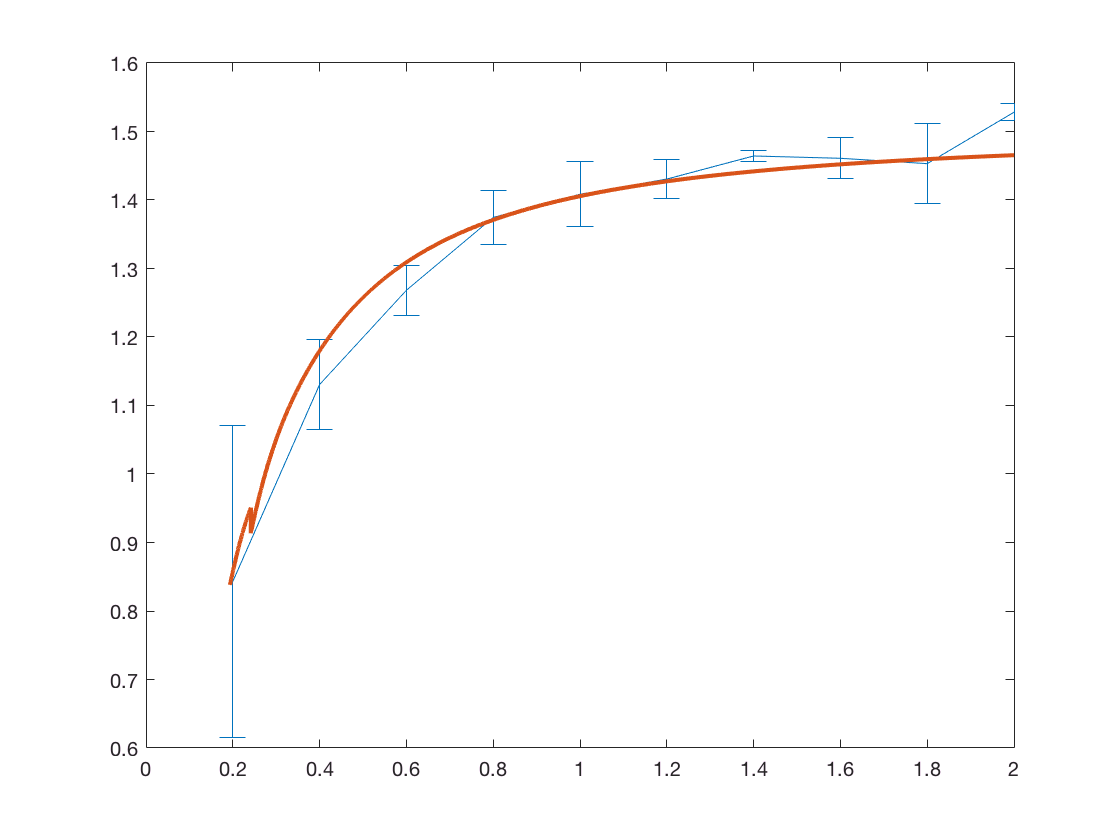

[Tbin,CvMean,CvStd]=BinLinear(Tt,CvTilde_Sim,0,3,0.2 );
% Tbin(CvStd>0.2)=[];
% CvMean(CvStd>0.2)=[];
% CvStd(CvStd>0.2)=[];
errorbar(Tbin,CvMean,CvStd);
% scatter(Tbin,CvMean);
hold on
plot(TTildeT,CvTildeT,'linewidth',2);
hold off
xlim([0,2])